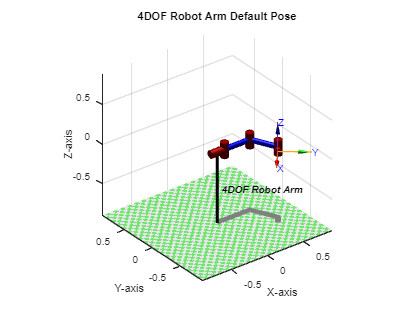



clear all               
close all               
clc                     

L1 = 0.1;  
L2 = 0.35; 
L3 = 0.35;  
L4 = 0.1; 

L(1) = Link('d', L1, 'a', 0, 'alpha', pi/2);       
L(2) = Link('d', 0, 'a', L2, 'alpha', 0);         
L(3) = Link('d', 0, 'a', L3, 'alpha', 0);         
L(4) = Link('d', 0, 'a', L4, 'alpha', 0);        

robot_arm = SerialLink(L, 'name', '4DOF Robot Arm');

%joint limit
robot_arm.qlim = [[-pi pi]; [-pi/4 7*pi/6]; [-5*pi/6 5*pi/6]; [-5*pi/6 5*pi/6]];

%adjust armbase
robot_arm.base = troty(pi/2); 

figure();
robot_arm.plot([0, 0, 0, 0]);
title('4DOF Robot Arm Default Pose');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
view(3);

%key poses
q_default = [0, 0, 0, 0];                    % Default pose
q_approach = [-0.5*pi, 0.36*pi, -0.816*pi, 0.4*pi]; % Position to approach the door handle
q_grip = [-0.5*pi, 0, 0, 0];                  % Position to grip the handle
q_open_door = [-0.5*pi, 0.5*pi, -0.36*pi, -0.36*pi]; % Position to open the door

num_steps = 20;

%Trajectories
q_traj_approach = jtraj(q_default, q_approach, num_steps);
q_traj_grip = jtraj(q_approach, q_grip, num_steps);
q_traj_open = jtraj(q_grip, q_open_door, num_steps);

for i = 1:num_steps
    robot_arm.plot(q_traj_approach(i, :), 'delay', 0.02);
end

for i = 1:num_steps
    robot_arm.plot(q_traj_grip(i, :), 'delay', 0.02);
end

for i = 1:num_steps
    robot_arm.plot(q_traj_open(i, :), 'delay', 0.02);
end